# **Section 4.2 • Economic Pipe Diameter**

**Source: **Janna, W. S. (2015). *Design of fluid thermal systems* (Fourth edition). Cengage Learning.

**Code by:** J.M. Nicolas Léger

[MATLAB® Basic Functions Reference](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf)

# **Assumptions & Glossary**

- **known flow rate (Q)**

- **unknown head loss**

- **circular pipeline**

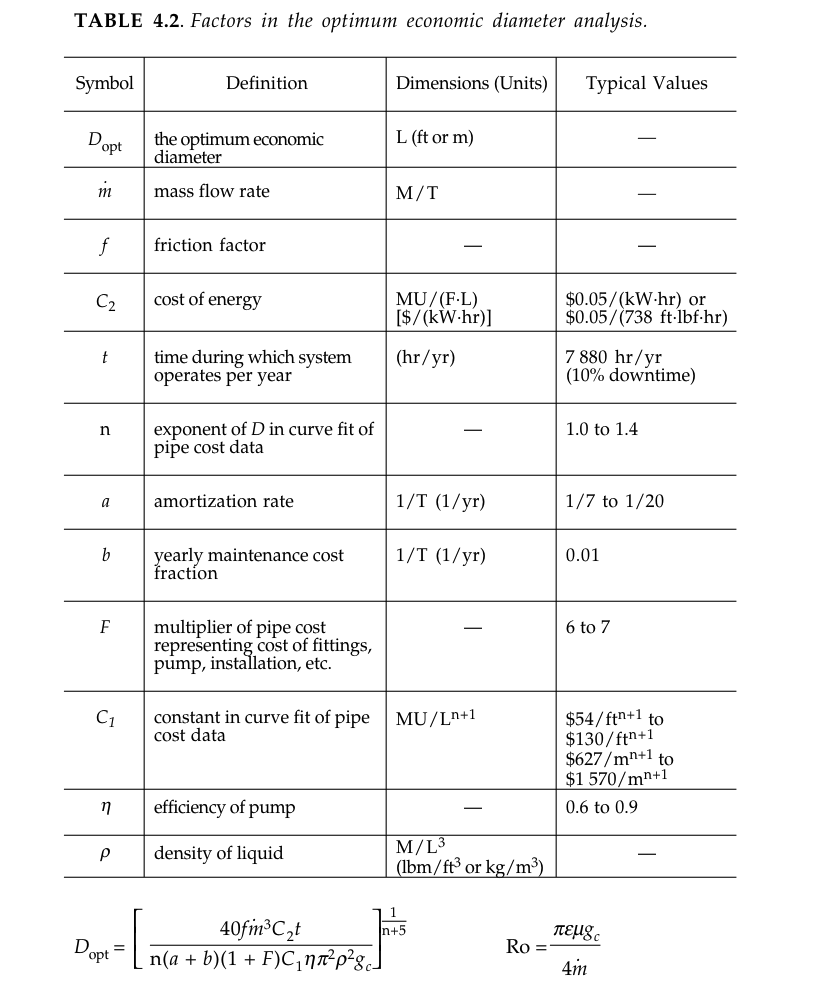

# **Example**

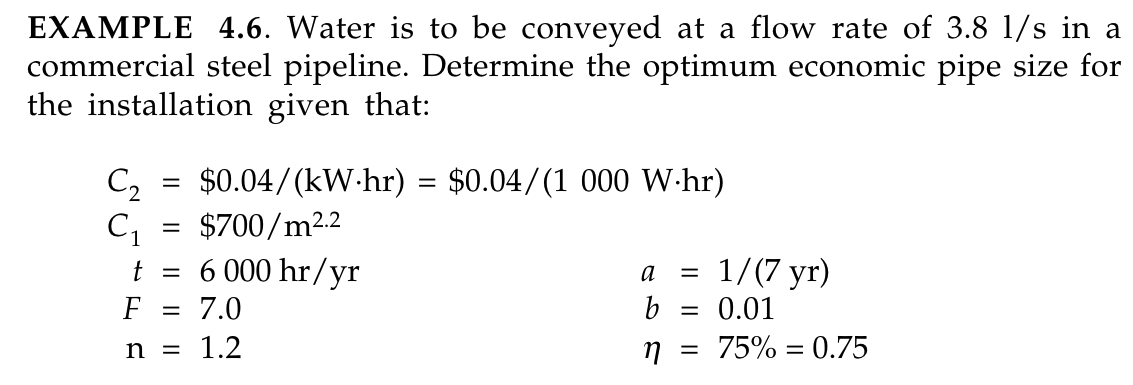

**Here the given values are:**

clc, clear
syms f Dopt Re

Cost of energy [$/(W·hr)]

C2= 0.00004 ;

Constant in curve fit of pipe cost data MU/Ln+1

C1=700;

Time during which system operates per year (hr/yr)

t= 6000 ;

Multiplier of pipe cost representing cost of fittings, pump, installation, etc.

F= 7;

Exponent of D in curve fit of pipe cost data

n= 1.2;

Amortization rate 1/T (1/yr)

a= 0.1429;% how to type a fraction in the real value is 1/7?

Yearly maintenance cost fraction 1/T (1/yr)

b= 0.01;

η efficiency of pump

eta=0.75;

**Properties of the given fluid**

Rho= 1000;
mu= 0.00089;

**Properties of the piping material**

Roughness factor (ε) m 

epsilon =0.000046 ;

**Given system volumetric flow rate (m^3/s)**

Q=0.0038;

**Calculations**

m=Rho*Q;  %mass flow rate kg/s
gc=1;     %mass unit·length unit force unit·time unit2
Dopt= ((40*f*(m^3)*C2*t)/(n*(a+b)*(1+F)*(C1*eta)*(pi^2)*(Rho^2)*gc))^(1/(n+5))  %the optimal economic diameter

$$Dopt = {\left(\frac{345224773632\,f}{4984455210696623125}\right)}^{5/31}$$

var = vpa(Dopt)

$$var = {\left(0.000000069260282024633076379398096618511\,f\right)}^{5/31}$$

fplot(Dopt,[0 0.0444])
grid on

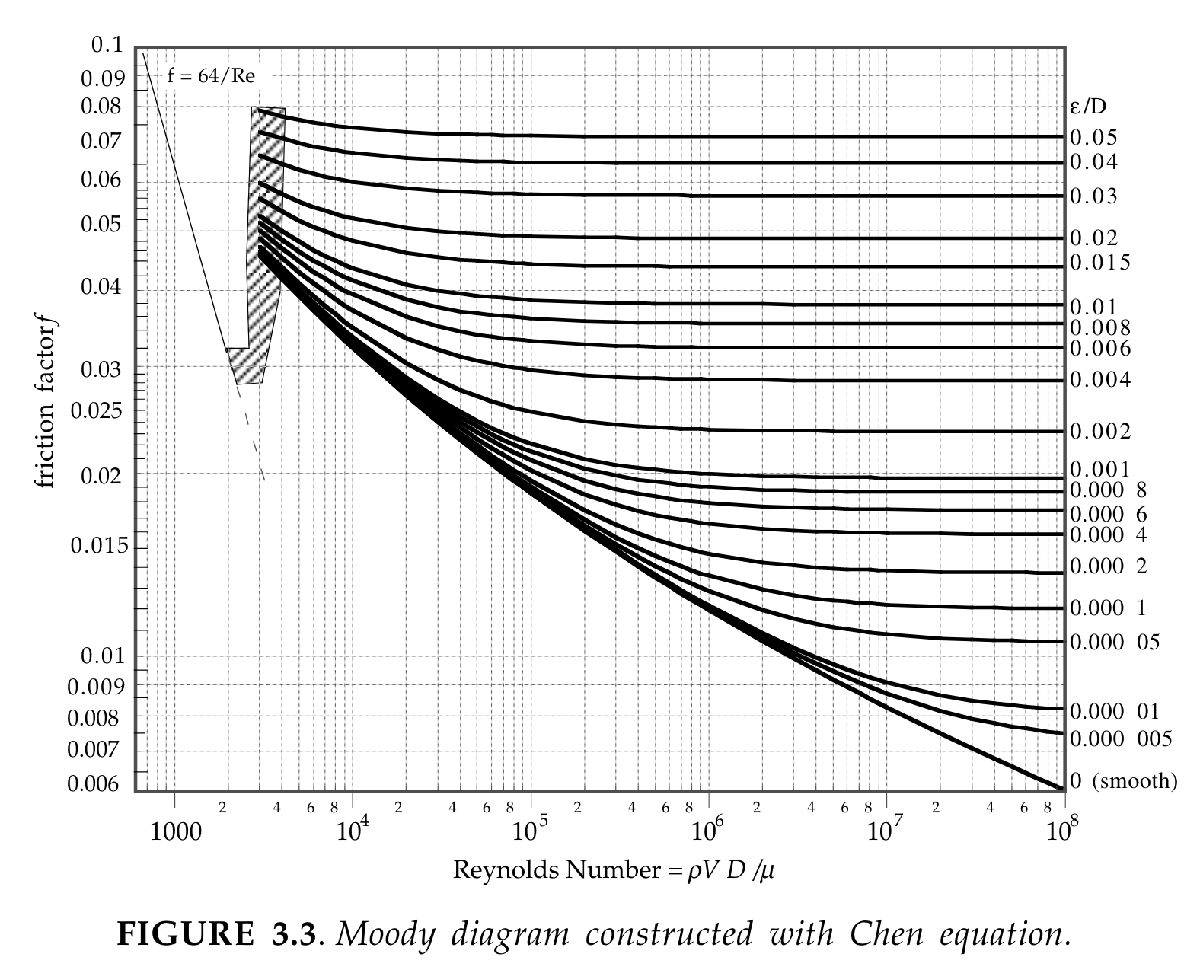

We start by assuming a diameter selected from a table of pipe sizes (such as Appendix Table D.1) or a diameter selected at random. Here we choose the latter. The Churchill equation for the friction factor is used. 

**The Reynolds number of the flow**

Dopt = 5; % You can choose any initial value (m)
% Set convergence tolerance
tolerance = 0.0001;
% Maximum number of iterations
max_iterations = 100;
% Initialize iteration counter
iteration = 0;
while iteration < max_iterations
    % Calculate Reynolds number
    Re = (4 * m) / (pi * Dopt * mu * gc);
    % Calculate friction factor based on Reynolds number
    if Re > 4000 % Turbulent
        % Churchill equation for turbulent flow
        B = (2.457 * log(1 / ((7 / Re) ^ 0.9 + (0.27 * epsilon / Dopt)))) ^ 16;
        C = (37530 / Re) ^ 16;
        f = 8 * (((8 / Re) ^ 12) + (1 / (B + C) ^ 1.5)) ^ (1 / 12)
        fprintf('Flow is turbulent (Re = %.2f)\n', Re);
    elseif Re < 2100 % Laminar
        f = 64 / Re
        fprintf('Flow is laminar (Re = %.2f)\n', Re);
    else % Transitional
        f = (((Re - 2000) / (4000 - 2000)) * (0.1 - 0.008)) + 0.008
        fprintf('Flow is transitional (Re = %.2f)\n', Re);
    end
    % Calculate a new estimate of Dopt using your economic diameter formula
    new_Dopt = ((40 * f * (m ^ 3) * C2 * t) / (n * (a + b) * (1 + F) * (C1 * eta) * (pi ^ 2) * (Rho ^ 2) * gc)) ^ (1 / (n + 5))
    
    % Check for convergence
    if abs(new_Dopt - Dopt) < tolerance
        break; % Convergence achieved
    end
    % Update Dopt for the next iteration
    Dopt = new_Dopt;
    iteration = iteration + 1
end

f = 0.0589

Flow is laminar (Re = 1087.26)


new_Dopt = 0.0443

iteration = 1

f = 0.0221

Flow is turbulent (Re = 122595.97)


new_Dopt = 0.0379

iteration = 2

f = 0.0224

Flow is turbulent (Re = 143605.10)


new_Dopt = 0.0380

% Output the final result
fprintf('Optimal economic diameter: %.6f\n', Dopt);

Optimal economic diameter: 0.037856


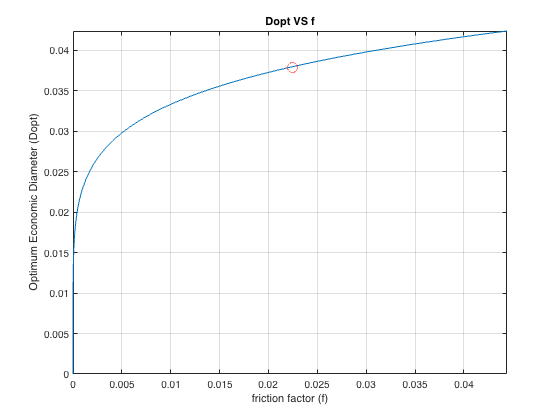

% Plot the final value of Dopt on the graph
hold on;
title('Dopt VS f');
xlabel('friction factor (f)');
ylabel('Optimum Economic Diameter (Dopt)');
plot(f, Dopt, 'ro', 'MarkerSize', 10); % 'ro' for red circle marker
hold off;